# ***Methylococcus capsulatus***** Monoculture S3 (30C, 37C, 42C, 47C)**

Loyal Murphy - February 8, 2023

### Initialization

clear variables
clc

### Import and separate the data

scans = dir('*.csv');
% Preallocate the matrices
C30_data = {};
C37_data = {};
C42_data = {};
C47_data = {};
c30 = 0;
c37 = 0;
c42 = 0;
c47 = 0;

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'Cap4') || startsWith(n,'Cap5') || startsWith(n,'Cap6')
        c30 = c30 + 1;
        C30_data{c30,1} = readtable(n);
        C30_data{c30,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'Cap1') || startsWith(n,'Cap2') || startsWith(n,'Cap3')
        c37 = c37 + 1;
        C37_data{c37,1} = readtable(n);
        C37_data{c37,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'C42')
        c42 = c42 + 1;
        C42_data{c42,1} = readtable(n);
        C42_data{c42,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'C47')
        c47 = c47 + 1;
        C47_data{c47,1} = readtable(n);
        C47_data{c47,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    end
end

to = datetime(2023,02,06,13,46,00); %Time CH4 was added (30 and 37)
to2 = datetime(2023,02,22,13,10,00); %Time CH4 was added (42 and 47)

### Get the averages and standard deviations of the data

pts30 = length(C30_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts30 
    C30_ave(j) = mean([C30_data{j,1}.Abs(C30_data{j,1}.nm == 600),...
        C30_data{j+pts30,1}.Abs(C30_data{j+pts30,1}.nm == 600),...
        C30_data{j+2*pts30,1}.Abs(C30_data{j+2*pts30,1}.nm == 600)]);
    C30_std(j) = std([C30_data{j,1}.Abs(C30_data{j,1}.nm == 600),...
        C30_data{j+pts30,1}.Abs(C30_data{j+pts30,1}.nm == 600),...
        C30_data{j+2*pts30,1}.Abs(C30_data{j+2*pts30,1}.nm == 600)],1);
    C30_times(j) = hours(mean([C30_data{j,2},...
        C30_data{j+pts30,2},...
        C30_data{j+2*pts30,2}]) - to);
end

pts37 = length(C37_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts37
    C37_ave(j) = mean([C37_data{j,1}.Abs(C37_data{j,1}.nm == 600),...
        C37_data{j+pts37,1}.Abs(C37_data{j+pts37,1}.nm == 600),...
        C37_data{j+2*pts37,1}.Abs(C37_data{j+2*pts37,1}.nm == 600)]);
    C37_std(j) = std([C37_data{j,1}.Abs(C37_data{j,1}.nm == 600),...
        C37_data{j+pts37,1}.Abs(C37_data{j+pts37,1}.nm == 600),...
        C37_data{j+2*pts37,1}.Abs(C37_data{j+2*pts37,1}.nm == 600)],1);
    C37_times(j) = hours(mean([C37_data{j,2},...
        C37_data{j+pts37,2},...
        C37_data{j+2*pts37,2}]) - to);
end

pts42 = length(C42_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts42
    C42_ave(j) = mean([C42_data{j,1}.Abs(C42_data{j,1}.nm == 600),...
        C42_data{j+pts42,1}.Abs(C42_data{j+pts42,1}.nm == 600),...
        C42_data{j+2*pts42,1}.Abs(C42_data{j+2*pts42,1}.nm == 600)]);
    C42_std(j) = std([C42_data{j,1}.Abs(C42_data{j,1}.nm == 600),...
        C42_data{j+pts42,1}.Abs(C42_data{j+pts42,1}.nm == 600),...
        C42_data{j+2*pts42,1}.Abs(C42_data{j+2*pts42,1}.nm == 600)],1);
    C42_times(j) = hours(mean([C42_data{j,2},...
        C42_data{j+pts42,2},...
        C42_data{j+2*pts42,2}]) - to2);
end

pts47 = length(C47_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts47
    C47_ave(j) = mean([C47_data{j,1}.Abs(C47_data{j,1}.nm == 600),...
        C47_data{j+pts47,1}.Abs(C47_data{j+pts47,1}.nm == 600),...
        C47_data{j+2*pts47,1}.Abs(C47_data{j+2*pts47,1}.nm == 600)]);
    C47_std(j) = std([C47_data{j,1}.Abs(C47_data{j,1}.nm == 600),...
        C47_data{j+pts47,1}.Abs(C47_data{j+pts47,1}.nm == 600),...
        C47_data{j+2*pts47,1}.Abs(C47_data{j+2*pts47,1}.nm == 600)],1);
    C47_times(j) = hours(mean([C47_data{j,2},...
        C47_data{j+pts47,2},...
        C47_data{j+2*pts47,2}]) - to2);
end

% Dilution numbers
C30_factor = 1;
C37_factor = [1 1 1 1 1 5 5 8 10 20 20 20 20 20];
C42_factor = [1 1 3 3 5 8 10 10 20 20 20 20 20];
C47_factor = [1 1 3 3 5 8 10 10 20 20 20 20];

C30_ave = C30_ave.*C30_factor;
C30_std = C30_std.*C30_factor;

C37_ave = C37_ave.*C37_factor;
C37_std = C37_std.*C37_factor;

C42_ave = C42_ave.*C42_factor;
C42_std = C42_std.*C42_factor;

C47_ave = C47_ave.*C47_factor;
C47_std = C47_std.*C47_factor;

% Growth Rates
C30_mu_ave = log(C30_ave(2:end)./C30_ave(1:end-1))./diff(C30_times);
for j = 1:pts30-1
    C30_mu_std(j) = std([log(C30_data{j+1,1}.Abs(C30_data{j+1,1}.nm == 600)/C30_data{j,1}.Abs(C30_data{j,1}.nm == 600))/(hours(C30_data{j+1,2} - C30_data{j,2})),...
        log(C30_data{j+pts30+1,1}.Abs(C30_data{j+pts30+1,1}.nm == 600)/C30_data{j+pts30,1}.Abs(C30_data{j+pts30,1}.nm == 600))/(hours(C30_data{j+pts30+1,2} - C30_data{j+pts30,2})),...
        log(C30_data{j+2*pts30+1,1}.Abs(C30_data{j+2*pts30+1,1}.nm == 600)/C30_data{j+2*pts30,1}.Abs(C30_data{j+2*pts30,1}.nm == 600))/(hours(C30_data{j+2*pts30+1,2} - C30_data{j+2*pts30,2}))]);
end

C37_mu_ave = log(C37_ave(2:end)./C37_ave(1:end-1))./diff(C37_times);
for j = 1:pts37-1
    C37_mu_std(j) = std([log(C37_data{j+1,1}.Abs(C37_data{j+1,1}.nm == 600)/C37_data{j,1}.Abs(C37_data{j,1}.nm == 600))/(hours(C37_data{j+1,2} - C37_data{j,2})),...
        log(C37_data{j+pts37+1,1}.Abs(C37_data{j+pts37+1,1}.nm == 600)/C37_data{j+pts37,1}.Abs(C37_data{j+pts37,1}.nm == 600))/(hours(C37_data{j+pts37+1,2} - C37_data{j+pts37,2})),...
        log(C37_data{j+2*pts37+1,1}.Abs(C37_data{j+2*pts37+1,1}.nm == 600)/C37_data{j+2*pts37,1}.Abs(C37_data{j+2*pts37,1}.nm == 600))/(hours(C37_data{j+2*pts37+1,2} - C37_data{j+2*pts37,2}))]);
end

C42_mu_ave = log(C42_ave(2:end)./C42_ave(1:end-1))./diff(C42_times);
for j = 1:pts42-1
    C42_mu_std(j) = std([log(C42_data{j+1,1}.Abs(C42_data{j+1,1}.nm == 600)/C42_data{j,1}.Abs(C42_data{j,1}.nm == 600))/(hours(C42_data{j+1,2} - C42_data{j,2})),...
        log(C42_data{j+pts42+1,1}.Abs(C42_data{j+pts42+1,1}.nm == 600)/C42_data{j+pts42,1}.Abs(C42_data{j+pts42,1}.nm == 600))/(hours(C42_data{j+pts42+1,2} - C42_data{j+pts42,2})),...
        log(C42_data{j+2*pts42+1,1}.Abs(C42_data{j+2*pts42+1,1}.nm == 600)/C42_data{j+2*pts42,1}.Abs(C42_data{j+2*pts42,1}.nm == 600))/(hours(C42_data{j+2*pts42+1,2} - C42_data{j+2*pts42,2}))]);
end

C47_mu_ave = log(C47_ave(2:end)./C47_ave(1:end-1))./diff(C47_times);
for j = 1:pts47-1
    C47_mu_std(j) = std([log(C47_data{j+1,1}.Abs(C47_data{j+1,1}.nm == 600)/C47_data{j,1}.Abs(C47_data{j,1}.nm == 600))/(hours(C47_data{j+1,2} - C47_data{j,2})),...
        log(C47_data{j+pts47+1,1}.Abs(C47_data{j+pts47+1,1}.nm == 600)/C47_data{j+pts47,1}.Abs(C47_data{j+pts47,1}.nm == 600))/(hours(C47_data{j+pts47+1,2} - C47_data{j+pts47,2})),...
        log(C47_data{j+2*pts47+1,1}.Abs(C47_data{j+2*pts47+1,1}.nm == 600)/C47_data{j+2*pts47,1}.Abs(C47_data{j+2*pts47,1}.nm == 600))/(hours(C47_data{j+2*pts47+1,2} - C47_data{j+2*pts47,2}))]);
end

save('Cap_Trips.mat','C37_data','to','C37_factor')

### Plot the Data

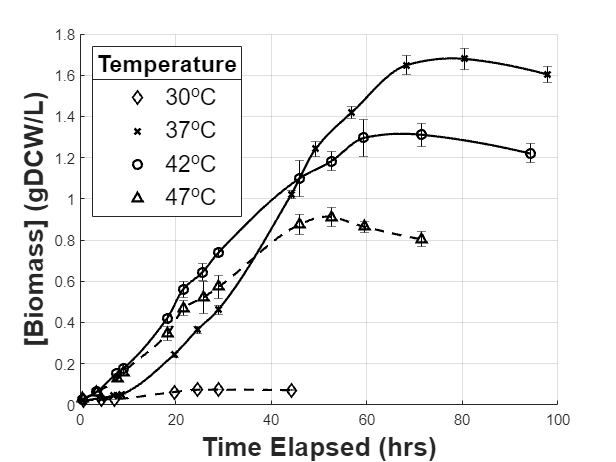

figure()
hold on
xq1 = linspace(C30_times(1),C30_times(end),200);
yq1 = makima(C30_times,C30_ave*0.235,xq1);
plot(C30_times,C30_ave*0.235,'kd',xq1,yq1,'k--','LineWidth',1.5);
errorbar(C30_times,C30_ave*0.235,C30_std*0.235,'k','LineStyle','none');

xq2 = linspace(C37_times(1),C37_times(end),200);
yq2 = makima(C37_times,C37_ave*0.235,xq2);
plot(C37_times,C37_ave*0.235,'kx',xq2,yq2,'k-','LineWidth',1.5);
errorbar(C37_times,C37_ave*0.235,C37_std*0.235,'k','LineStyle','none');

xq3 = linspace(C42_times(1),C42_times(end),200);
yq3 = makima(C42_times,C42_ave*0.235,xq3);
plot(C42_times,C42_ave*0.235,'ko',xq3,yq3,'k-','LineWidth',1.5);
errorbar(C42_times,C42_ave*0.235,C42_std*0.235,'k','LineStyle','none');

xq4 = linspace(C47_times(1),C47_times(end),200);
yq4 = makima(C47_times,C47_ave*0.235,xq4);
plot(C47_times,C47_ave*0.235,'k^',xq4,yq4,'k--','LineWidth',1.5);
errorbar(C47_times,C47_ave*0.235,C47_std*0.235,'k','LineStyle','none');
hold off

grid on
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold')
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold')
lgd = legend('30^{o}C','','','37^{o}C','','','42^{o}C','','','47^{o}C','','','location','northwest','FontSize',16);
title(lgd,'Temperature')
xlim([0 100])

%title('M. capsulatus Monoculture')
save('Cap_mono.mat','C30_times','C30_ave','C30_std','C37_times','C37_ave','C37_std','C42_times','C42_ave','C42_std','C47_times','C47_ave','C47_std')

### Growth Rate Determination

table(C30_mu_ave',C30_mu_std','VariableNames',{'mu30','std'})

ans = 6×2 table
       mu30          std    
    __________    __________

      0.058602      0.002723
      0.023765    0.00016654
      0.065182     0.0033837
      0.033649     0.0050065
     0.0029149     0.0019622
    -0.0025526    0.00042855


table(C37_mu_ave',C37_mu_std','VariableNames',{'mu37','std'})

ans = 13×2 table
       mu37          std   
    __________    _________

       0.13679    0.0061466
       0.10138    0.0070802
       0.11467    0.0051709
       0.11967     0.030186
         0.141    0.0055476
       0.08198    0.0066657
      0.054443     0.019831
      0.051944    0.0027745
      0.038456    0.0031503
      0.017689    0.0038096
       0.01302    0.0023166
     0.0014833    0.0058749
    -0.0026378    0.0027561


table(C42_mu_ave',C42_mu_std','VariableNames',{'mu42','std'})

ans = 12×2 table
       mu42          std    
    __________    __________

       0.26997      0.005927
       0.21159     0.0034016
        0.1002     0.0080964
      0.095091     0.0061827
      0.086212      0.015064
      0.033856     0.0039432
      0.041491      0.013838
      0.023464     0.0044431
      0.011027     0.0078998
      0.013402     0.0057839
    0.00099879     0.0082162
    -0.0031502    0.00067397


table(C47_mu_ave',C47_mu_std','VariableNames',{'mu47','std'})

ans = 11×2 table
       mu47          std   
    __________    _________

       0.25154    0.0024993
       0.16717     0.027877
       0.17343     0.072575
      0.084409     0.011461
      0.092081     0.015419
      0.025783     0.021024
      0.028737     0.017666
      0.025036    0.0032316
     0.0060017       0.0121
    -0.0077871     0.004307
    -0.0060826    0.0022207



%Display maximum growth rate
[C30_max,C30idx] = max(C30_mu_ave);
[C37_max,C37idx] = max(C37_mu_ave);
[C42_max,C42idx] = max(C42_mu_ave);
[C47_max,C47idx] = max(C47_mu_ave);

disp(['The maximum growth rate of M. capsulatus at 30C is ',num2str(round(C30_max,3)),' 1/hr between ',num2str(round(C30_times(C30idx),2)),' and ',num2str(round(C30_times(C30idx+1),2)),' hours.'])

The maximum growth rate of M. capsulatus at 30C is 0.065 1/hr between 7.07 and 19.71 hours.


disp(['The maximum growth rate of M. capsulatus at 37C is ',num2str(round(C37_max,3)),' 1/hr between ',num2str(round(C37_times(C37idx),2)),' and ',num2str(round(C37_times(C37idx+1),2)),' hours.'])

The maximum growth rate of M. capsulatus at 37C is 0.141 1/hr between 8.59 and 19.63 hours.


disp(['The maximum growth rate of M. capsulatus at 42C is ',num2str(round(C42_max,3)),' 1/hr between ',num2str(round(C42_times(C42idx),2)),' and ',num2str(round(C42_times(C42idx+1),2)),' hours.'])

The maximum growth rate of M. capsulatus at 42C is 0.27 1/hr between 0.39 and 3.42 hours.


disp(['The maximum growth rate of M. capsulatus at 47C is ',num2str(round(C47_max,3)),' 1/hr between ',num2str(round(C47_times(C47idx),2)),' and ',num2str(round(C47_times(C47idx+1),2)),' hours.'])

The maximum growth rate of M. capsulatus at 47C is 0.252 1/hr between 0.45 and 3.48 hours.


### Total Nitrogen and Phosphorus Left in Solution

t_nut = [0.6,24.75,49.25,98];
N = [126.14,127.68,125.28;...
    70.96,75.28,76.72;...
    55.92,56.80,62.24;...
    48.75,49.11,51.03];
P = [22.36,22.12,22.08;...
    2.47,2.53,2.95;...
    2.39,2.28,2.33;...
    2.34,2.27,2.31];

save Cap_nut.mat t_nut N P 

for i = 1:length(t_nut)
    Nave(i,:) = [mean(N(i,1:3))];
    Pave(i,:) = [mean(P(i,1:3))];
    Nstd(i,:) = [std(N(i,1:3),1)];
    Pstd(i,:) = [std(P(i,1:3),1)];
end

N_remove_rate = -diff(N)./diff(t_nut)';
P_remove_rate = -diff(P)./diff(t_nut)';
N_remove_ave = mean(N_remove_rate,2);
P_remove_ave = mean(P_remove_rate,2);
N_remove_std = std(N_remove_rate,1,2);
P_remove_std = std(P_remove_rate,1,2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

table(N_remove_ave,N_remove_std,P_remove_ave,P_remove_std)

ans = 3×4 table
    N_remove_ave    N_remove_std    P_remove_ave    P_remove_std
    ____________    ____________    ____________    ____________

       2.1551          0.11239          0.80897        0.012942 
      0.65306         0.072182         0.012925       0.0092015 
      0.17826          0.03681       0.00054701      0.00034865 


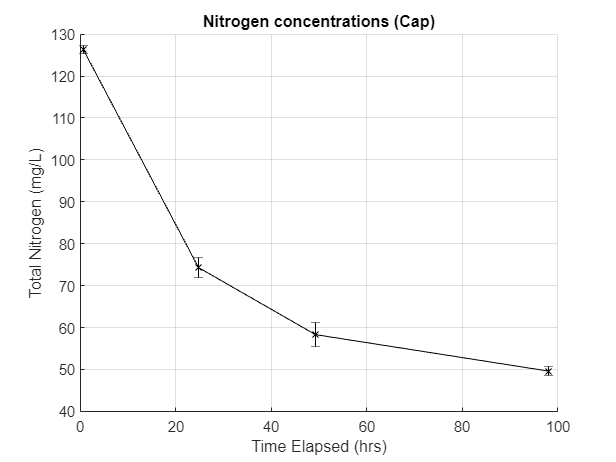


figure()
hold on
plot(t_nut,Nave(:,1),'kx-')
errorbar(t_nut,Nave(:,1),Nstd(:,1),'k','LineStyle','none');
hold off

grid on 
xlabel('Time Elapsed (hrs)')
ylabel('Total Nitrogen (mg/L)')
title("Nitrogen concentrations (Cap)") 

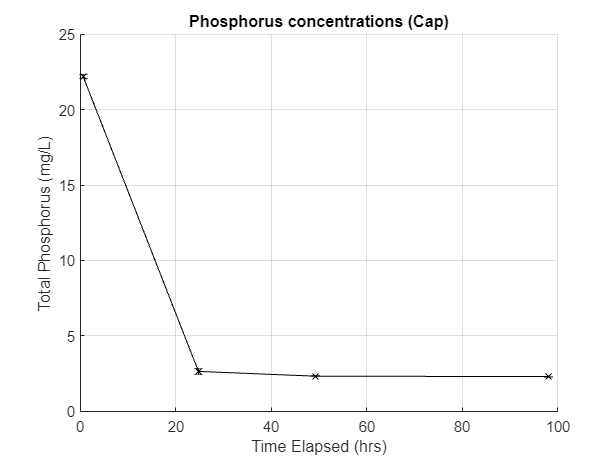


figure()
hold on
plot(t_nut,Pave(:,1),'kx-');
errorbar(t_nut,Pave(:,1),Pstd(:,1),'k','LineStyle','none');
hold off

grid on 
xlabel('Time Elapsed (hrs)')
ylabel('Total Phosphorus (mg/L)')
title("Phosphorus concentrations (Cap)")

### Comparisons of Wavelength Scans Over Time

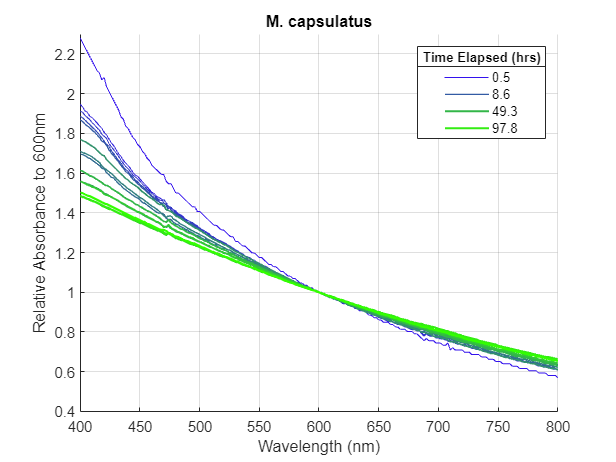

%Capsulatus Monoculture Wavelength Scans
figure()
%%%%%%%%%%%%%%%%%%%%%%%%%%% 37C
%subplot(1,2,1)
hold on
for m = 1:pts37
    rel = C37_data{m,1}.Abs(C37_data{1,1}.nm == 600);
    plot(C37_data{m,1}.nm,C37_data{m,1}.Abs/rel,'Color',[0.2,m/pts37,1-(m/pts37)],'LineStyle','-','LineWidth',0.5+m/pts37)
end
hold off

xlabel('Wavelength (nm)')
ylabel('Relative Absorbance to 600nm')
%title('Vessel 1 (Cap @ 37C)')
title('M. capsulatus')
%lgd = legend(num2str(round(C37_times',1)));
lgd = legend(num2str(round(C37_times(1),1)),'','','',num2str(round(C37_times(5),1)),'','','','',num2str(round(C37_times(10),1)),'','',num2str(round(C37_times(14),1)));
title(lgd,'Time Elapsed (hrs)')
axis([400 800 0.4 2.3])
grid on

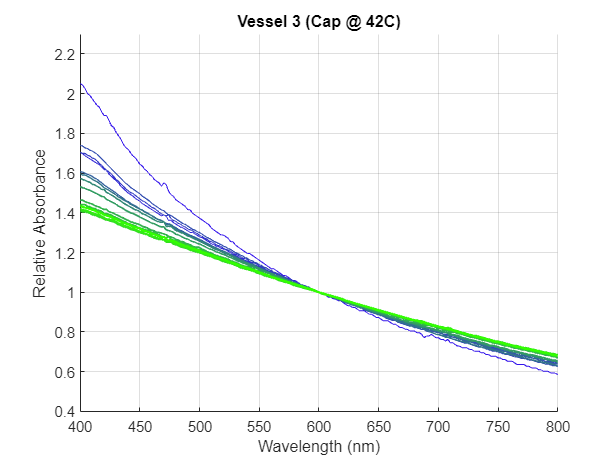

%%%%%%%%%%%%%%%%%%%%%%%%%%% 42C
figure()
%subplot(1,2,2)
hold on
for m = 1:pts42
    rel = C42_data{m,1}.Abs(C42_data{1,1}.nm == 600);
    plot(C42_data{m,1}.nm,C42_data{m,1}.Abs/rel,'Color',[0.2,m/pts42,1-(m/pts42)],'LineStyle','-','LineWidth',0.5+m/pts42)
end
hold off

xlabel('Wavelength (nm)')
ylabel('Relative Absorbance')
title('Vessel 3 (Cap @ 42C)')
axis([400 800 0.4 2.3])
grid on